## Ex1

1. Usando a função quantiz do Matlab efetue a quantização do sinal 2-a) para 𝑛𝑏𝑖𝑡 = 2, 3 e 4 bits de quantização. O número de níveis e quantização é dado por ∆= 𝐴𝑚𝑝 2 𝑛𝑏𝑖𝑡 .Compare o sinal quantizado com o sinal original.

clear; clc; close all;

Ta = 0.02; t_max = 5; fa = 2;
t = (0:Ta:t_max - Ta)

t =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800



x = sin(2*pi*t)

x =          0    0.1253    0.2487    0.3681    0.4818    0.5878    0.6845    0.7705    0.8443    0.9048    0.9511    0.9823    0.9980    0.9980    0.9823    0.9511    0.9048    0.8443    0.7705    0.6845    0.5878    0.4818    0.3681    0.2487    0.1253    0.0000   -0.1253   -0.2487   -0.3681   -0.4818   -0.5878   -0.6845   -0.7705   -0.8443   -0.9048   -0.9511   -0.9823   -0.9980   -0.9980   -0.9823   -0.9511   -0.9048   -0.8443   -0.7705   -0.6845   -0.5878   -0.4818   -0.3681   -0.2487   -0.1253



max_x = max(x);
min_x = abs(min(x));
amplitude = max_x + min_x;

n_bits = [2,3,4]; aux = 1

aux = 1


for n_bit = n_bits
    delta = amplitude / 2^n_bit;
    
    sig = x;
    partition = -min_x + delta:delta: max_x - delta;
    codebook = -min_x + delta/2:delta: max_x - delta/2;
    
    [index, quants] = quantiz(sig, partition, codebook);
  
    [Y, t_rec] = ReconstroiSinal(quants, Ta);
    
    figure(aux); aux = aux + 1;
    plot(t, quants, t, sig)
    grid on
end

Ex2

Compare também o espectro do sinal original com os sinais quantizados para 2, 3 e 4bits. O que pode concluir?

Nota: use a função espectro do trabalho anterior.

clear; clc; close all;

Ta = 0.02; t_max = 5; fa = 2;
t = (0:Ta:t_max - Ta)

t =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800



x = sin(2*pi*t)

x =          0    0.1253    0.2487    0.3681    0.4818    0.5878    0.6845    0.7705    0.8443    0.9048    0.9511    0.9823    0.9980    0.9980    0.9823    0.9511    0.9048    0.8443    0.7705    0.6845    0.5878    0.4818    0.3681    0.2487    0.1253    0.0000   -0.1253   -0.2487   -0.3681   -0.4818   -0.5878   -0.6845   -0.7705   -0.8443   -0.9048   -0.9511   -0.9823   -0.9980   -0.9980   -0.9823   -0.9511   -0.9048   -0.8443   -0.7705   -0.6845   -0.5878   -0.4818   -0.3681   -0.2487   -0.1253



max_x = max(x);
min_x = abs(min(x));
amplitude = max_x + min_x;

n_bits = [2,3,4]; aux = 1

aux = 1

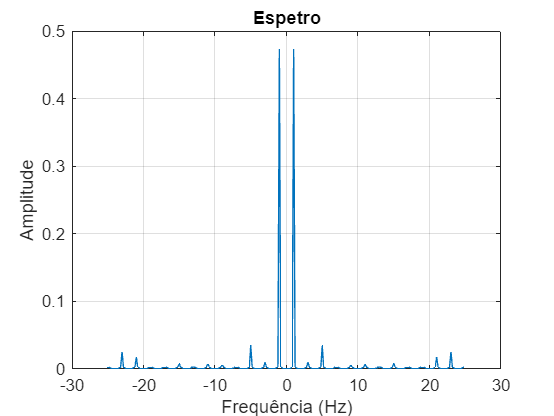

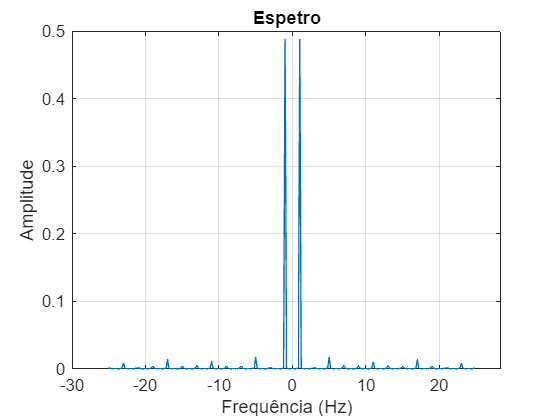

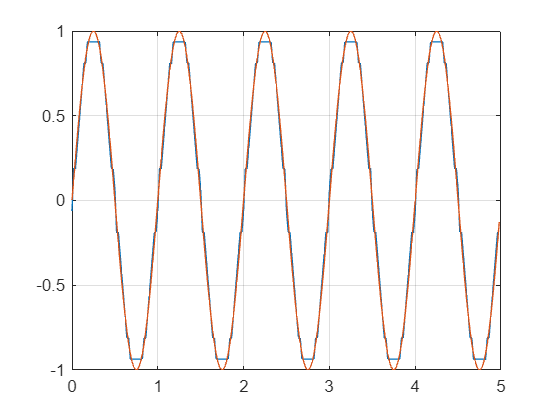


for n_bit = n_bits
    delta = amplitude / 2^n_bit;
    
    sig = x;
    partition = -min_x + delta:delta: max_x - delta;
    codebook = -min_x + delta/2:delta: max_x - delta/2;
    
    [index, quants] = quantiz(sig, partition, codebook);
  
    [Y, t_rec] = Espectro(quants, Ta);

    plot(t, quants, t, sig)
end